close all; clc; clearvars;

TrainingFeatures_norm = readmatrix("TrainingFeatures_norm_gray.csv");
TrainingFeatures_glau = readmatrix("TrainingFeatures_glau_gray.csv");
TestingFeatures_norm = readmatrix("TestingFeatures_norm_gray.csv");
TestingFeatures_glau = readmatrix("TestingFeatures_glau_gray.csv");

X_train = [TrainingFeatures_glau'; TrainingFeatures_norm'];
Y_train = [ones(size(TrainingFeatures_glau, 2), 1); zeros(size(TrainingFeatures_norm, 2), 1)];
X_test = [TestingFeatures_glau'; TestingFeatures_norm'];
Y_test = [ones(size(TestingFeatures_glau, 2), 1); zeros(size(TestingFeatures_norm, 2), 1)];


i = 22;
rng(i)

Mdl = fitcnet(X_train, Y_train, ...
 'LayerSizes', 10, ...
 'Activations', 'relu', 'Lambda', 0, 'IterationLimit', 1000, ...
 'Standardize', true, 'ClassNames', [false; true]);

[Y_pred, scores_gray] = predict(Mdl, X_test);
[~, ~, ~, auc_test] = perfcurve(Y_test, scores_gray(:,1), 1)

auc_test = 0.3824

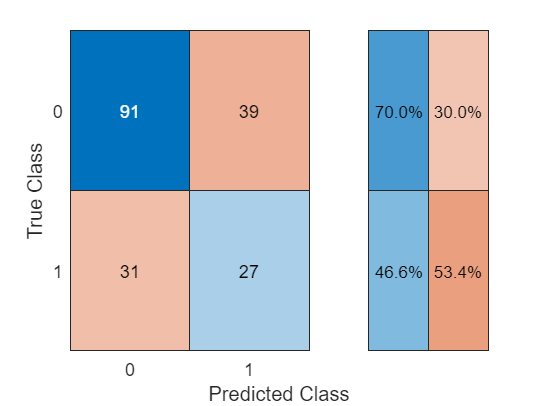


figure
confusionchart(Y_test, Y_pred, 'RowSummary','row-normalized');

TrainingFeatures_norm = readmatrix("TrainingFeatures_norm_red.csv");
TrainingFeatures_glau = readmatrix("TrainingFeatures_glau_red.csv");
TestingFeatures_norm = readmatrix("TestingFeatures_norm_red.csv");
TestingFeatures_glau = readmatrix("TestingFeatures_glau_red.csv");

X_train = [TrainingFeatures_glau'; TrainingFeatures_norm'];
Y_train = [ones(size(TrainingFeatures_glau, 2), 1); zeros(size(TrainingFeatures_norm, 2), 1)];
X_test = [TestingFeatures_glau'; TestingFeatures_norm'];
Y_test = [ones(size(TestingFeatures_glau, 2), 1); zeros(size(TestingFeatures_norm, 2), 1)];

rng(i)
Mdl = fitcnet(X_train, Y_train, ...
 'LayerSizes', 10, ...
 'Activations', 'relu', 'Lambda', 0, 'IterationLimit', 1000, ...
 'Standardize', true, 'ClassNames', [false; true]);

[Y_pred, scores_red] = predict(Mdl, X_test);
[~, ~, ~, auc_test] = perfcurve(Y_test, scores_red(:,1), 1)

auc_test = 0.4065

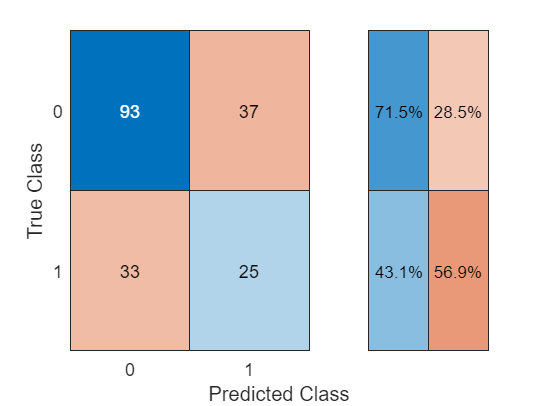


figure
confusionchart(Y_test, Y_pred, 'RowSummary','row-normalized');

TrainingFeatures_norm = readmatrix("TrainingFeatures_norm_green.csv");
TrainingFeatures_glau = readmatrix("TrainingFeatures_glau_green.csv");
TestingFeatures_norm = readmatrix("TestingFeatures_norm_green.csv");
TestingFeatures_glau = readmatrix("TestingFeatures_glau_green.csv");

X_train = [TrainingFeatures_glau'; TrainingFeatures_norm'];
Y_train = [ones(size(TrainingFeatures_glau, 2), 1); zeros(size(TrainingFeatures_norm, 2), 1)];
X_test = [TestingFeatures_glau'; TestingFeatures_norm'];
Y_test = [ones(size(TestingFeatures_glau, 2), 1); zeros(size(TestingFeatures_norm, 2), 1)];

rng(i)
Mdl = fitcnet(X_train, Y_train, ...
 'LayerSizes', 10, ...
 'Activations', 'relu', 'Lambda', 0, 'IterationLimit', 1000, ...
 'Standardize', true, 'ClassNames', [false; true]);

[Y_pred, scores_green] = predict(Mdl, X_test);
[~, ~, ~, auc_test] = perfcurve(Y_test, scores_green(:,1), 1)

auc_test = 0.4324

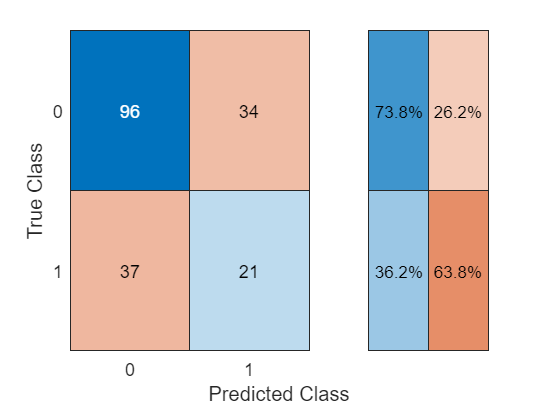


figure
confusionchart(Y_test, Y_pred, 'RowSummary','row-normalized');

TrainingFeatures_norm = readmatrix("TrainingFeatures_norm_blue.csv");
TrainingFeatures_glau = readmatrix("TrainingFeatures_glau_blue.csv");
TestingFeatures_norm = readmatrix("TestingFeatures_norm_blue.csv");
TestingFeatures_glau = readmatrix("TestingFeatures_glau_blue.csv");

X_train = [TrainingFeatures_glau'; TrainingFeatures_norm'];
Y_train = [ones(size(TrainingFeatures_glau, 2), 1); zeros(size(TrainingFeatures_norm, 2), 1)];
X_test = [TestingFeatures_glau'; TestingFeatures_norm'];
Y_test = [ones(size(TestingFeatures_glau, 2), 1); zeros(size(TestingFeatures_norm, 2), 1)];

rng(i)
Mdl = fitcnet(X_train, Y_train, ...
 'LayerSizes', 10, ...
 'Activations', 'relu', 'Lambda', 0, 'IterationLimit', 1000, ...
 'Standardize', true, 'ClassNames', [false; true]);

[Y_pred, scores_blue] = predict(Mdl, X_test);

acc_test = sum(strcmp(Y_pred, Y_test)) / length(Y_test)

acc_test = 0

[~, ~, ~, auc_test] = perfcurve(Y_test, scores_blue(:,1), 1)

auc_test = 0.4816

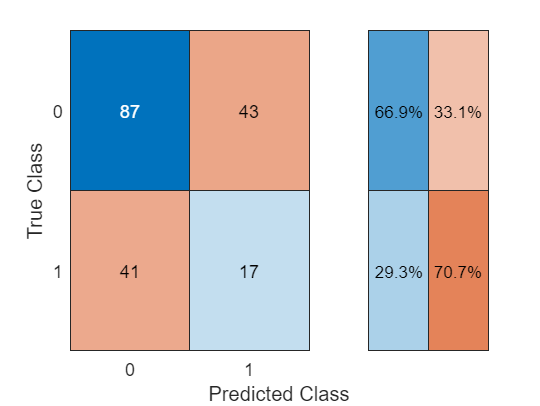


figure
confusionchart(Y_test, Y_pred, 'RowSummary','row-normalized');

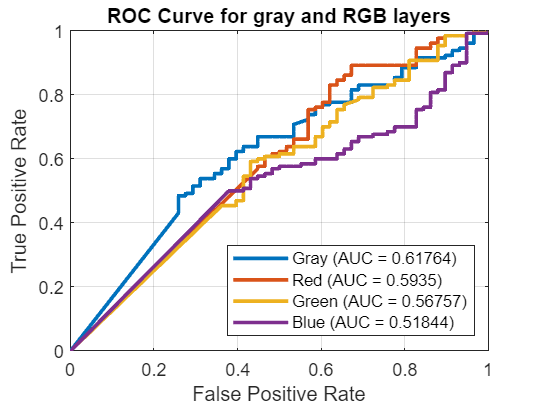

[X_gray,Y_gray,T_gray,AUC_gray] = perfcurve(Y_test, scores_gray(:,1), 0);
[X_red,Y_red,T_red,AUC_red] = perfcurve(Y_test, scores_red(:,1), 0);
[X_green,Y_green,T_green,AUC_green] = perfcurve(Y_test, scores_green(:,1), 0);
[X_blue,Y_blue,T_blue,AUC_blue] = perfcurve(Y_test, scores_blue(:,1), 0);

figure
plot(X_gray,Y_gray, 'LineWidth', 2)
hold on
plot(X_red,Y_red, 'LineWidth', 2)
plot(X_green,Y_green, 'LineWidth', 2)
plot(X_blue,Y_blue, 'LineWidth', 2)

xlabel('False Positive Rate')
ylabel('True Positive Rate')
title('ROC Curve for gray and RGB layers')
grid on
legend(['Gray (AUC = ' num2str(AUC_gray) ')'], ['Red (AUC = ' num2str(AUC_red) ')'], ['Green (AUC = ' num2str(AUC_green) ')'], ['Blue (AUC = ' num2str(AUC_blue) ')'], 'Location', 'southeast')
hold off